#      Face Recognition using Principal Component Analysis

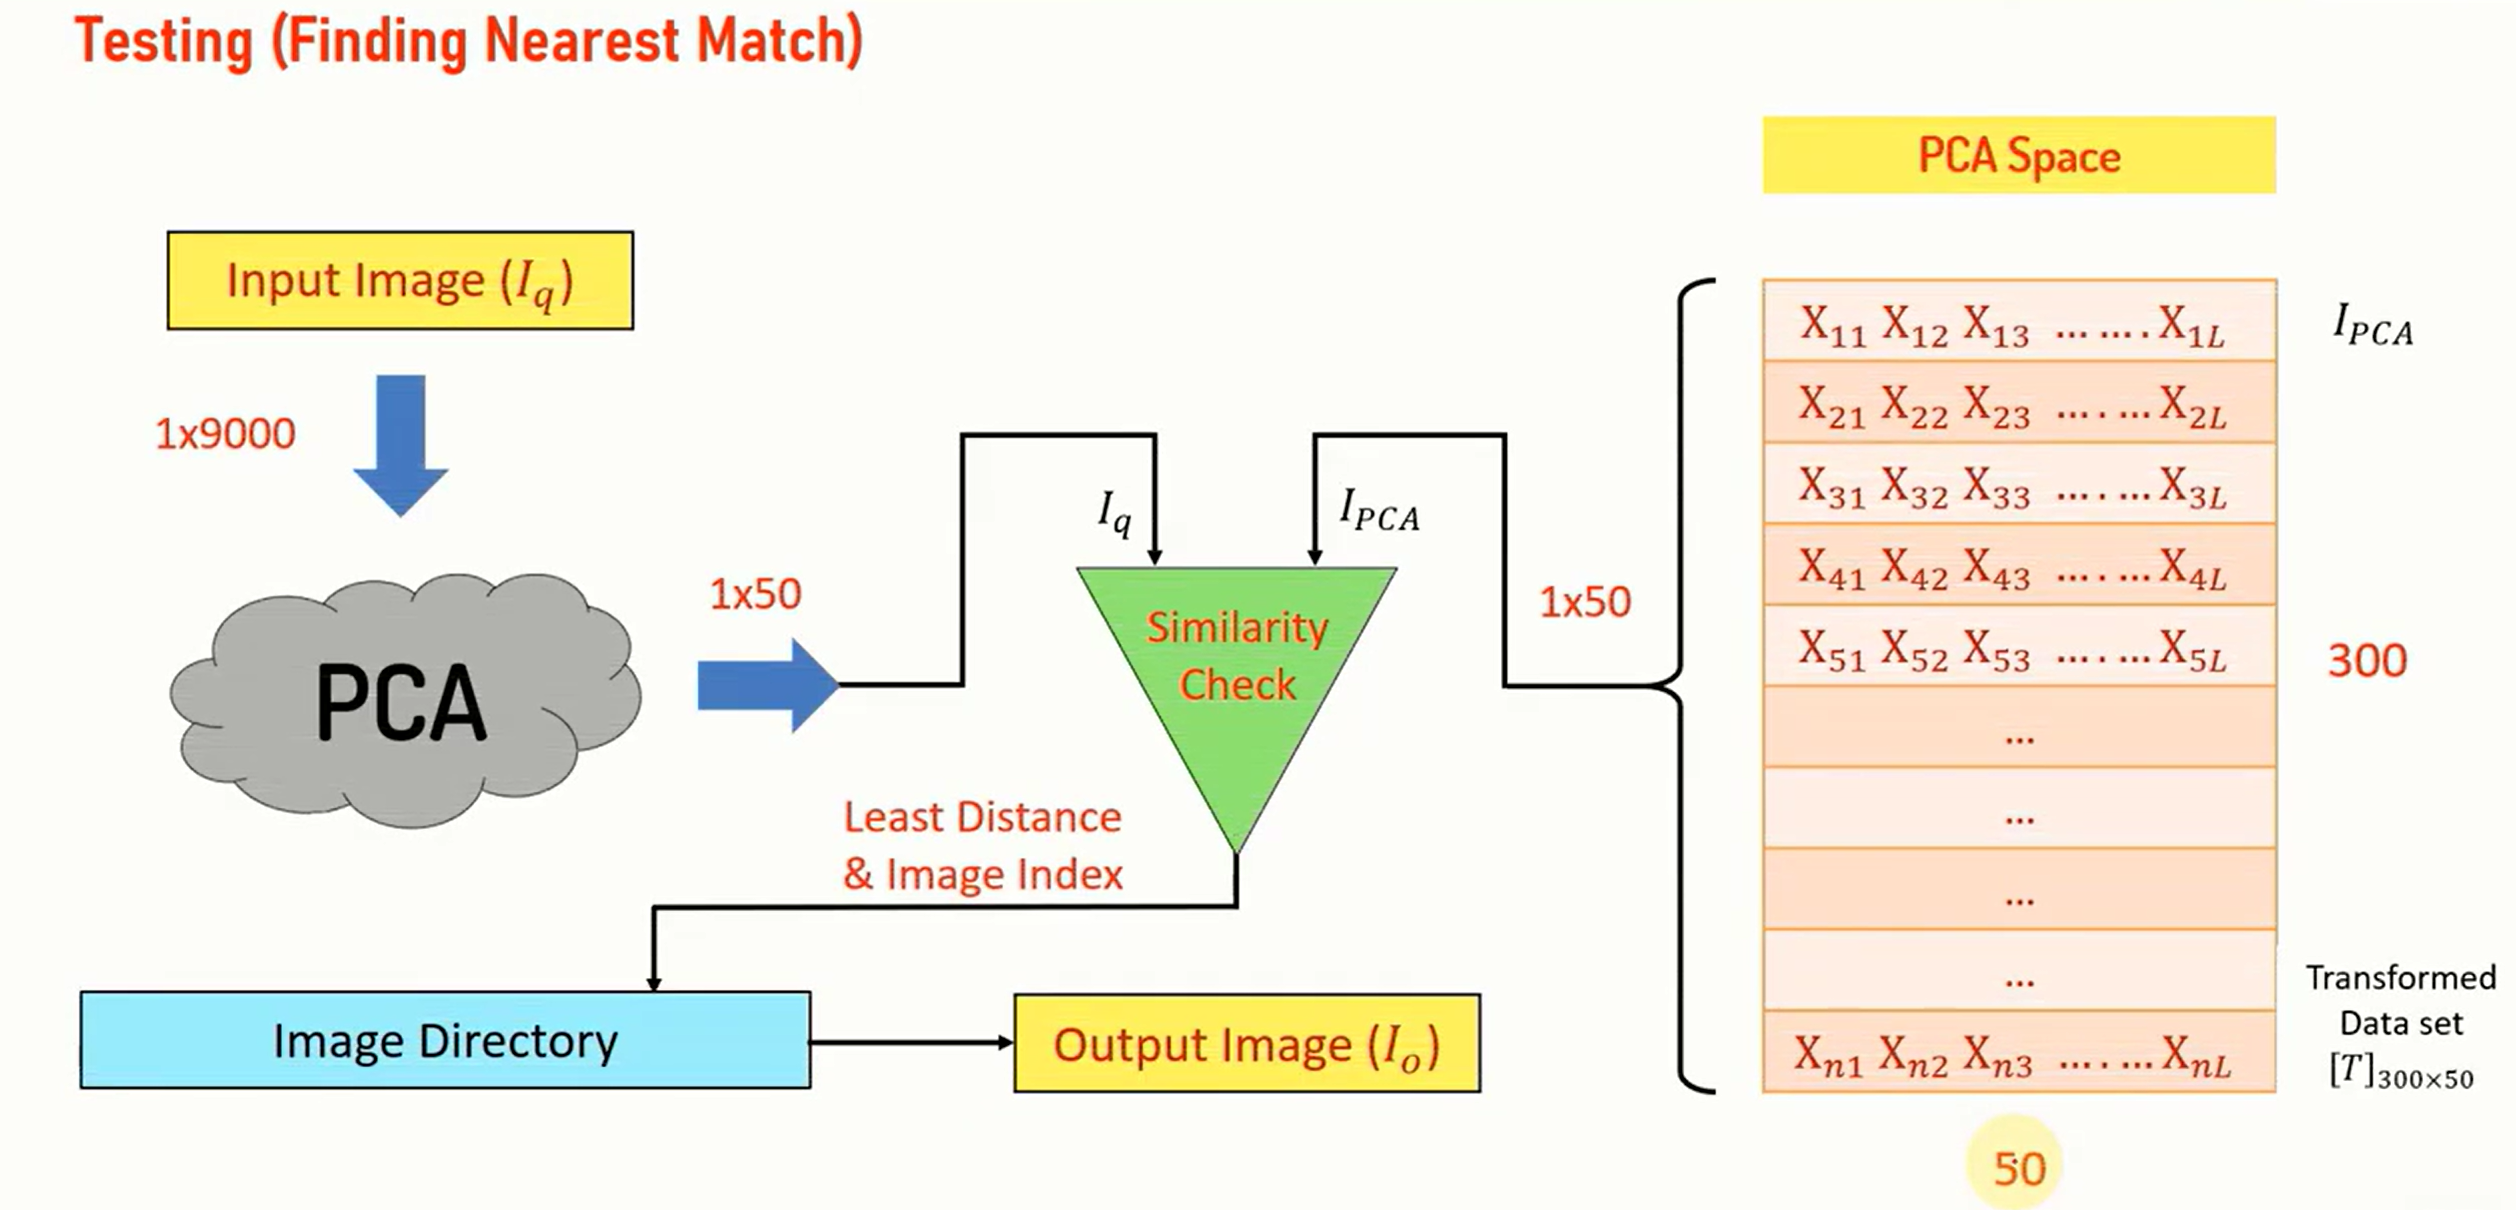

clc;
load pcadb;  % Load the PCA database
% pcadb loads the following variables:
% Image size [M=100, N=90]
% Mean Image [m]
% Reduced Eigen Vectors transformation matrix [Ppca]
% Transformed dataset matrix [T]


% Select the input image using a file dialog
[filename, pathname] = uigetfile('*.*', 'Select the input image');
filewithpath = fullfile(pathname, filename);

% Read and preprocess the input image
img = imread(filewithpath);
imgo = img;  % Save original image for display
img = rgb2gray(img);  % Convert image to grayscale
img = imresize(img, [M, N]);  % Resize image to match PCA database size
img = double(reshape(img, [1, M * N]));  % Reshape image to a 1D vector and convert to double

% Project the query image into the PCA space
imgpca = (img - m) * Ppca;  % Center and project the image onto PCA space


% Initialize distance array to store distances from the query image to each database image
distarray = zeros(n, 1);

% Calculate the distance between the query image and each image in the PCA database
for i = 1:n
    distarray(i) = sum(abs(T(i, :) - imgpca));  % Sum of absolute differences
end

% Find the image in the database with the minimum distance to the query image
[result, indx] = min(distarray);

% Load the recognized image from the database based on the index
resultimg = imread(sprintf('%d.jpg', indx));


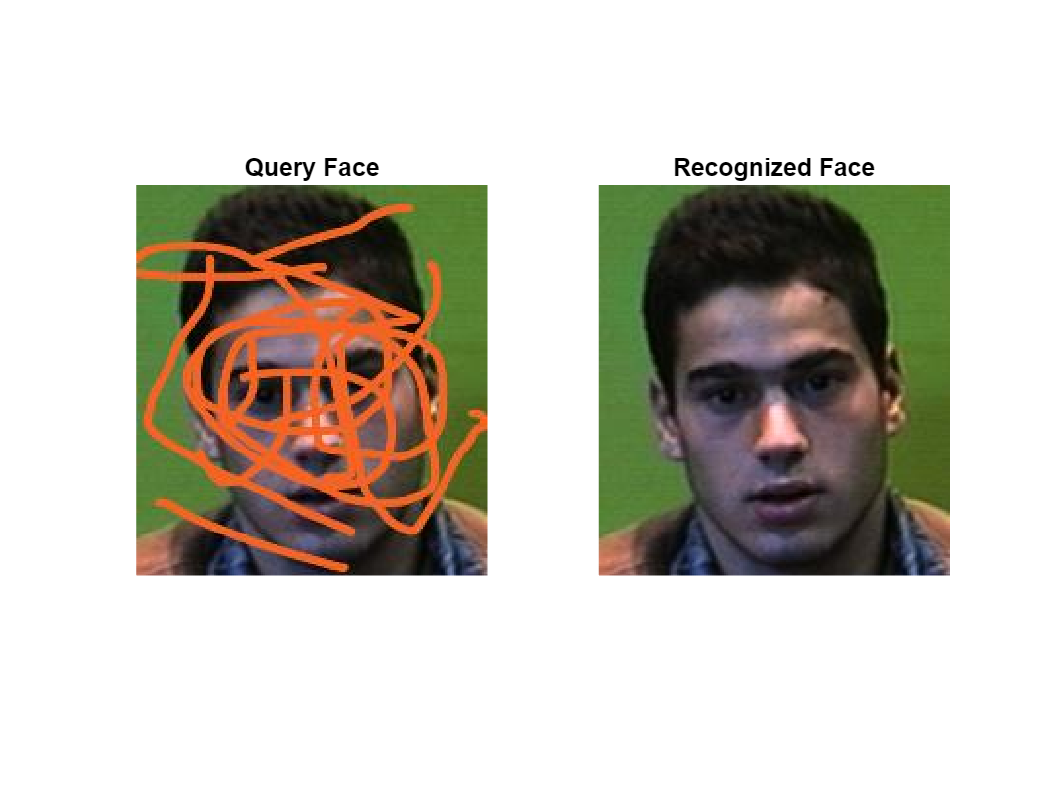

% Plot the original query image and the recognized image side by side
subplot(1, 2, 1);
imshow(imgo);
title('Query Face');

subplot(1, 2, 2);
imshow(resultimg);
title('Recognized Face');